# MLSE using Viterbi Algorithm

## K.MOHITH PRAKASH

## 22EC01002

## ISI Channel Mode

M = 4;
PAM = [-3 -1 1 3];
Fz = [0.6, -1, 0.8];
mu = 2;
in_length = 1e4;
IN = randi([1, M], 1, in_length);
ak = PAM(IN);
ak = [[-3, -3], ak, [-3, -3]];
state1 = repmat(PAM, 1, length(PAM));
state2 = repelem(PAM, length(PAM));
states = [state2; state1];
wk = conv(ak, Fz);
wk = wk(3:end-2);
snr_db = 0:2:16;
snr = 10.^(snr_db / 10);
N0 = 1 ./ snr;
AWGN = sqrt(N0(:) / 2) .* randn(1, in_length + 2);
transmitted = wk + AWGN;
numInputSymbols = M;
numOutputSymbols = M;
numStates = M^mu;

## State Diagram

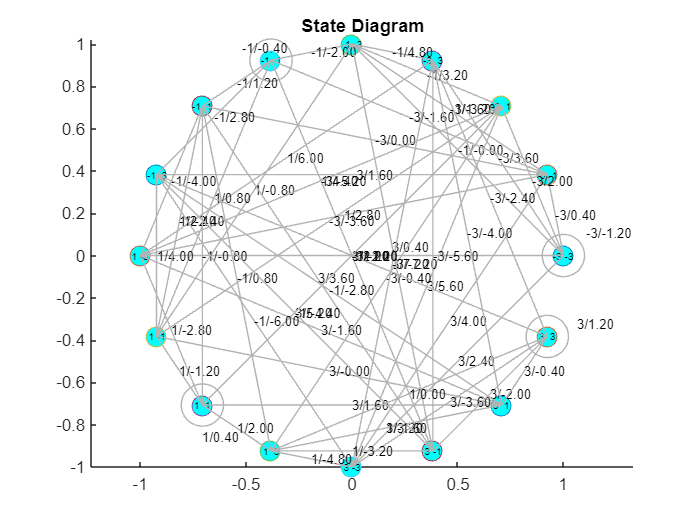

figure;
hold on;
title('State Diagram');
axis equal;

% Set up state diagram parameters
theta = linspace(0, 2*pi, numStates+1);
statePositions = [cos(theta(1:end-1)); sin(theta(1:end-1))]';
l = numStates * length(PAM);
currentstate = zeros(2, l);
input = zeros(1, l);
next_state = zeros(2, l);

% Plot state nodes
for i = 1:numStates
    plot(statePositions(i,1), statePositions(i,2), 'o', 'MarkerSize',12,'MarkerFaceColor', 'cyan');text(statePositions(i,1), statePositions(i,2),num2str([states(1,i),states(2,i)]), 'HorizontalAlignment', 'center', 'FontSize', 6);
end

% Initialize index counter
k = 1;

% Plot state transitions with arrows and self-loops
for i = 1:numStates
    for j = 1:M
        % Set current state and input
        currentstate(:, k) = states(:, i);
        input(k) = PAM(j);
        % Find the current and next state indices
        currentIndex = find(ismember(states', currentstate(:, k)', 'rows'));
        next_state(:, k) = [input(k); states(1, i)];
        nextIndex = find(ismember(states', next_state(:, k)', 'rows'));
        % Calculate transition values and labels
        f_value = Fz(1) * PAM(j) + Fz(2) * states(1, i) + Fz(3) * states(2, i);
        transition_label = sprintf('%d/%.2f', input(k), f_value);

        if currentIndex == nextIndex
            % Self-transition: Draw a small circular loop with arrow
            loop_radius = 0.1;
            % Adjust loop size as needed
            angle_offset = pi/4;
            % Offset for loop positioning
            angle = theta(currentIndex) + angle_offset;
            loop_x = statePositions(currentIndex, 1) + loop_radius * cos(angle+linspace(0, 2*pi, 50));
            loop_y = statePositions(currentIndex, 2) + loop_radius * sin(angle+linspace(0, 2*pi, 50));
            plot(loop_x, loop_y, 'Color', [0.7 0.7 0.7]);
            % Place label near the self-loop
            text(statePositions(currentIndex, 1) + 1.5*loop_radius * cos(angle), ...
            statePositions(currentIndex, 2) + 1.5*loop_radius * sin(angle), ...
            transition_label, 'FontSize', 8, 'Color', 'k');

        else
            % Draw transition line and label with quiver for an arrow
            dx = statePositions(nextIndex, 1) - statePositions(currentIndex, 1);
            dy = statePositions(nextIndex, 2) - statePositions(currentIndex, 2);
            quiver(statePositions(currentIndex, 1), statePositions(currentIndex,2),...
            dx, dy, 0, 'Color', [0.7 0.7 0.7], 'MaxHeadSize', 0.05);
            % Midpoint for transition label
            midPoint = (statePositions(currentIndex, :)+statePositions(nextIndex, :)) / 2;
            text(midPoint(1), midPoint(2), transition_label, 'FontSize', 8,'Color','k');
        end
        % Increment index counter
        k = k + 1;
    end
end
hold off

## Trellis Diagram

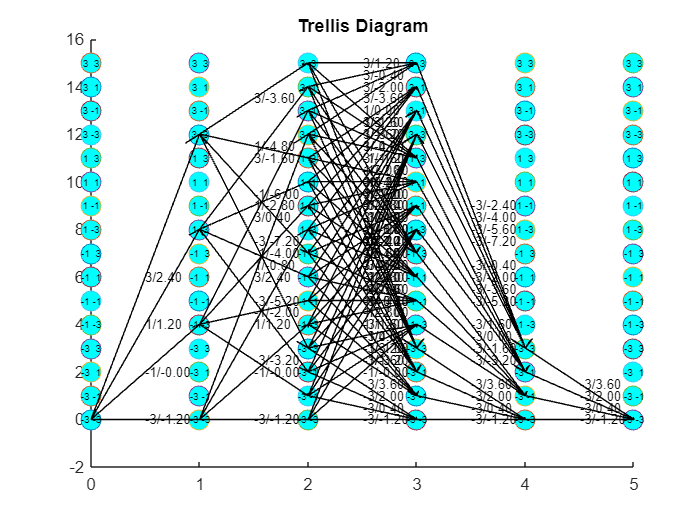

numStates = size(states, 2);
numTimeSteps = 6; % Set this to the number of time steps you want to display
% Define spacing between states and time steps

ySpacing = 1;
xSpacing = 1;

% Initialize coordinates for each state at each time step
statePositions = zeros(numStates, numTimeSteps, 2);

% Set positions for each state across time steps
for t = 1:numTimeSteps
    for i = 1:numStates
        statePositions(i, t, :) = [(t - 1) * xSpacing, (i - 1) * ySpacing];
    end
end

% Plot the states for each time step
figure;
hold on;
title('Trellis Diagram');
% Plot each state as a circle at each time step
for t = 1:numTimeSteps
    for i = 1:numStates
        % Plot the state circle
        plot(statePositions(i, t, 1), statePositions(i, t, 2), 'o','MarkerSize',12, 'MarkerFaceColor', 'cyan');
        % Label each state with its index number
        text(statePositions(i, t, 1), statePositions(i, t, 2), ...
        num2str([states(1,i), states(2,i)]), ...
        'HorizontalAlignment', 'center', 'FontSize', 6);
    end
end

% Define the allowed states for specific time steps
allowedStatesT1 = 1; % Only state 1 for t=1 and t=numTimeSteps-1
allowedStatesT2 = 1:M:M^mu;
allowedStatesT3 = [1, 2, 3, 4];
% Loop through each time step and states
for t = 1:numTimeSteps
% Determine allowed states based on the time step
    if t == 1 || t == numTimeSteps
        stateIndices = allowedStatesT1;
    elseif t == 2
        stateIndices = allowedStatesT2;
    elseif t == numTimeSteps-1
        stateIndices = allowedStatesT3;
    else
        stateIndices = 1:numStates;
    end
    for i = 1:numStates
        % Check if the current state is allowed based on the time step
        if ismember(i, stateIndices)
            for j = 1:M
                % Define current and next states
                currentState = states(:, i)';
                input = PAM(j);
                next_state = [PAM(j), states(1, i)];
                % Find the index of the next state in the states matrix
                [~, nextIndex] = ismember(next_state, states', 'rows');
                if t==numTimeSteps-2 && ~ismember(nextIndex, allowedStatesT3)
                continue;
                elseif t==numTimeSteps-1 && ~ismember(nextIndex, allowedStatesT1)
                continue;
                else
                % Only draw if the next state is found
                    if nextIndex > 0 && t<numTimeSteps
                        % Draw arrow from current state at time t to next state at time
                        quiver(statePositions(i, t, 1), statePositions(i, t, 2), ...
                        statePositions(nextIndex, t+1, 1) - statePositions(i,t,1),...
                        statePositions(nextIndex, t+1, 2) - statePositions(i,t,2),...
                        0, 'MaxHeadSize', 0.1, 'Color', 'black');
                        % Label the transition with input and output
                        f = Fz(1)*PAM(j)+Fz(2)*states(1, i)+Fz(3)*states(2, i);
                        transitionLabel = sprintf('%d/%.2f', input, f);
                        midX = (statePositions(i, t, 1) + statePositions(nextIndex,t+1,1)) / 2;
                        midY = (statePositions(i, t, 2) + statePositions(nextIndex,t+1,2)) / 2;
                        text(midX, midY, transitionLabel, 'FontSize', 8, 'Color','black');
                    end
                end
            end
        end
    end
end
hold off;

nextIndex = zeros(numStates, M);
for i = 1:numStates
    for j = 1:M
        input = PAM(j);
        next_state = [input, states(1, i)];
        [~, calculatedNextIndex] = ismember(next_state, states', 'rows');
        nextIndex(i, j) = calculatedNextIndex;
    end
end
R = [2, 4, 8, 10, 20];
SER = zeros(5, length(N0));
idx = 1;
for j = 1:length(R)
    N = R(j);
    for i = 1:length(N0)
        decoded = viterbi(N, transmitted(i,:), mu, states, PAM, Fz, nextIndex);
        SER(idx, i) = sum(decoded ~= IN);
    end
    idx = idx + 1;
end

## Plotting

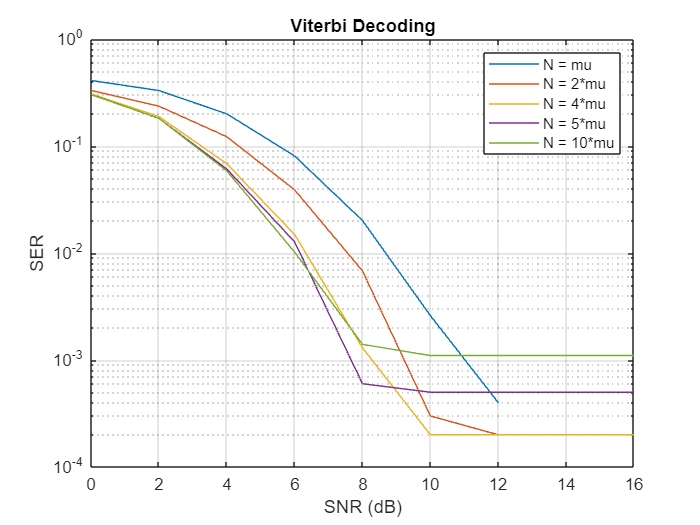

semilogy(repmat(snr_db, [5 1])', (SER ./ in_length)');
xlabel('SNR (dB)');
ylabel('SER');
grid on;
title('Viterbi Decoding');
legend('N = mu', 'N = 2*mu', 'N = 4*mu', 'N = 5*mu', 'N = 10*mu');

## Inference from the plots

As N≥4μ, we notice that the increase in the Symbol Error Rate (SER) becomes less significant. Theoretically,the

SER should continue to increase as N increases. However, based on the simulation results, I have observedthat

keeping N at values like 4μ or 5μ yields the best balance in terms of both latency and error minimization.

function decoded_symbols = viterbi(N, transmitted, mu, states, PAM, fk, nextIndex)
    total_symbols = length(transmitted); % Total received symbols including termination
    segment_length = N + mu; % Number of stages per segment
    num_segments = ceil(total_symbols / mu); % Total decoding segments
    num_states = size(nextIndex, 1);
    minCost = inf(num_states, segment_length + 1);
    minCost(1, 1) = 0; % Start with zero cost at the initial state
    survivor_paths = zeros(num_states, segment_length + 1); % Survivor paths for each state
    decoded_symbols = []; % Output decoded symbols
    for segment_idx = 1:(num_segments-1)
        % Set segment boundaries
        start_idx = (segment_idx - 1) * mu + 1;
        end_idx = min(segment_idx * mu + N, total_symbols);
        % Viterbi Decoding for Each Stage in the Segment
        for k = 1:(end_idx - start_idx + 1)
            for i = 1:num_states
                for j = 1:4 % Assuming 4-PAM
                    output_symbol = PAM(j) * fk(1) + states(1, i) * fk(2)+states(2, i) * fk(3);
                    cost = abs(transmitted(start_idx + k - 1) - output_symbol)^2;
                    cumulative_cost = minCost(i, k) + cost;
                    next_state = nextIndex(i, j);
                    if cumulative_cost < minCost(next_state, k + 1)
                        minCost(next_state, k + 1) = cumulative_cost;
                        survivor_paths(next_state, k + 1) = i;
                    end
                end
            end
        end
        % Traceback to Identify Survivor Path for First mu Symbols
            [~, final_state] = min(minCost(:, segment_length + 1));
            n = final_state;
            segment_decoded = zeros(1, length(segment_length));
        for i = (end_idx - start_idx + 1):-1:1
            segment_decoded(i) = survivor_paths(final_state, segment_length + 1 -(end_idx - start_idx + 1 - i));
            final_state = survivor_paths(final_state, segment_length + 1 -(end_idx- start_idx + 1 - i));
        end
            segment_decoded = segment_decoded(1:3);
            % Append the decoded symbols for this segment
            % Mapping decoded states back to symbols
            input_symbol_index = zeros(1, length(segment_decoded) - 1);
        for i = 1:(length(segment_decoded) - 1)
            % Find the index of the next state in possible_next_states
            input_symbol_index(i) = find(nextIndex(segment_decoded(i), :)==segment_decoded(i + 1), 1);
        end
        % input_symbol_index=input_symbol_index(1:2);
        decoded_symbols = [decoded_symbols, input_symbol_index];
        % Reset path metrics for next segment
        temp_Cost = minCost(:, mu + 1);
        minCost(:, :) = inf; % Reinitialize for the next segment
        minCost(:, 1) = temp_Cost;
    end
end